# Eksamenssæt december 2020

## Opg. 1: Covariance matricer

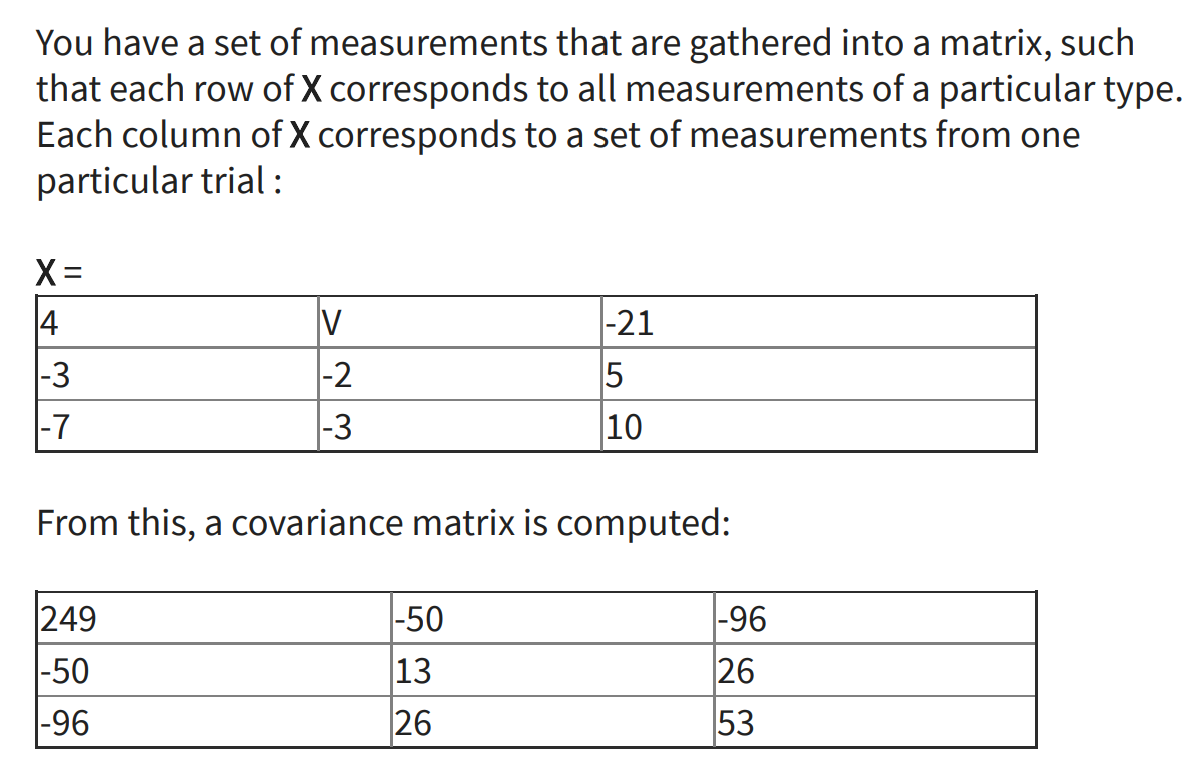

Wht is the missing value V?

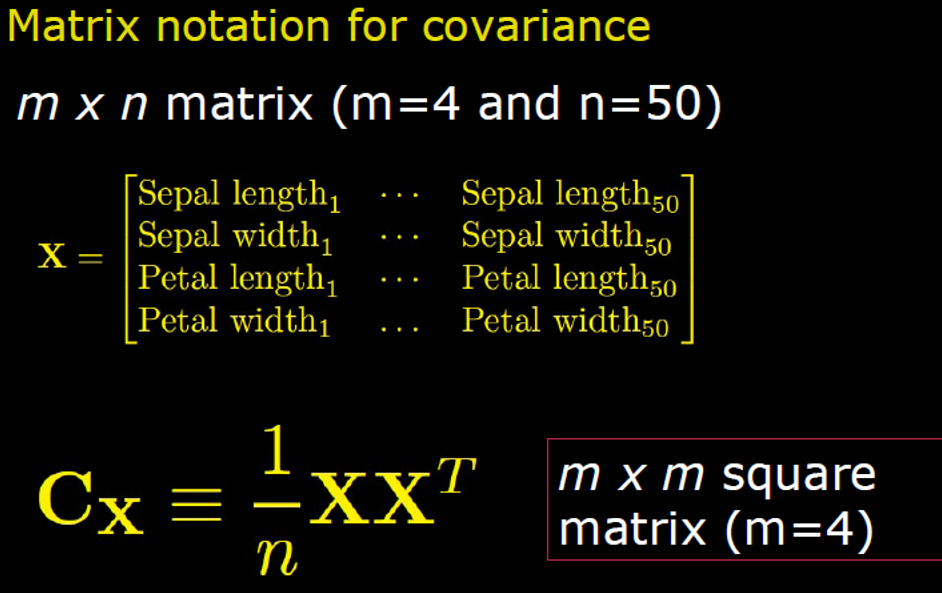

for V=[17,4,13,6,7] 
X = [4 V -21; -3 -2 5; -7 -3 10]
% K = cov(X)
%C = 1/3 *X *(X')
C = exam_funcs.covariance_matrix(X)
end

X =      4    17   -21
    -3    -2     5
    -7    -3    10


C =   248.6667  -50.3333  -96.3333
  -50.3333   12.6667   25.6667
  -96.3333   25.6667   52.6667


X =      4     4   -21
    -3    -2     5
    -7    -3    10


C =   157.6667  -41.6667  -83.3333
  -41.6667   12.6667   25.6667
  -83.3333   25.6667   52.6667


X =      4    13   -21
    -3    -2     5
    -7    -3    10


C =   208.6667  -47.6667  -92.3333
  -47.6667   12.6667   25.6667
  -92.3333   25.6667   52.6667


X =      4     6   -21
    -3    -2     5
    -7    -3    10


C =   164.3333  -43.0000  -85.3333
  -43.0000   12.6667   25.6667
  -85.3333   25.6667   52.6667


X =      4     7   -21
    -3    -2     5
    -7    -3    10


C =   168.6667  -43.6667  -86.3333
  -43.6667   12.6667   25.6667
  -86.3333   25.6667   52.6667


## Opg. 2 g afstanden ude i virkeligheden: 

Your camera has a CCD chip that measures 6.5 x 4.5 mm and an image taken with the camera has 7800 x 5400 pixels. It can be assumed that f=b=2.3 mm. The camera has been used to take an image of a 50 cm high reference object. On the image, the object is 400 pixels high. 

How far away from the camera is the reference object?

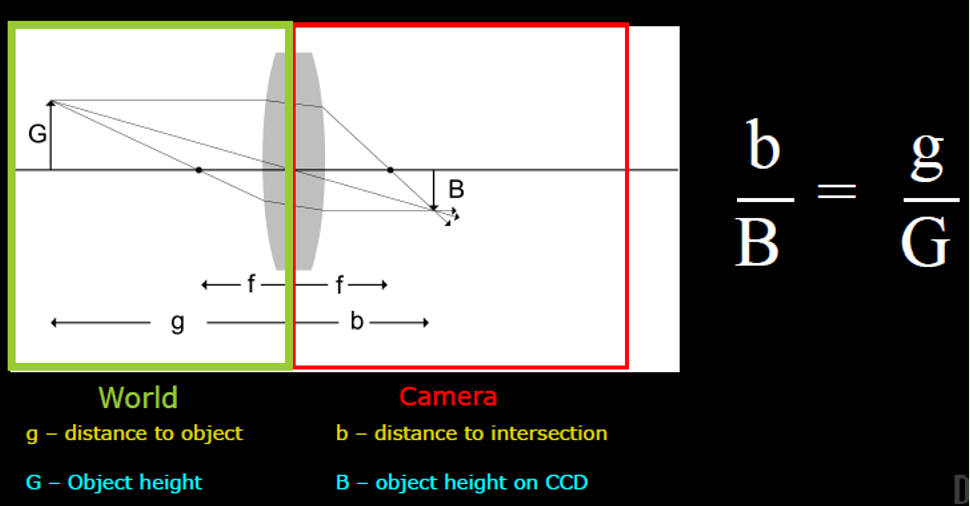

G = 500; %mm
b = 2.3;
B = 400; %pixels  % omregn pixels til mm 
B = B*4.5/5400;

g = (b*G)/B

g = 3450

%Derfor svar B 3.45 m

## Opg. 3 B størrelsen inde i kameraet: 

You have taken a photo of a DTU sign with a **width of 1.2 m from a distance of 7 m. **

The camera has a **CCD chip that measures (bredde)5.8 x (højde)4.2 mm and the image has 6960 x 5040 pixels**. It can be assumed that **f=b=1.5 mm. **

How many pixels wide will the sign be in the photo? 

clc; clear; close all; 
g = 7000; %7m i millimeter
G = 1200;
f = 1.5;
b= 1.5;



B = (b*G)/g

B = 0.2571

% omregn nu til pixels 
B = B*6960/5.8

B = 308.5714

%Derfor svar D 309



## Opg. 4: Field of view

You have taken a photo of building with a camera with a horizontal fieldof-view of 42 degrees. The building can just fit into the photo and the photo is taken from a distance of 7 m. 

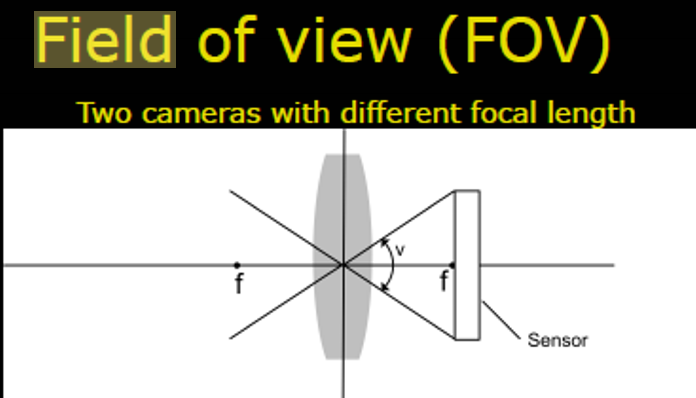

How wide is the building? 

Den_forste =tand(21)*7

Den_forste = 2.6870

Den_anden =tand(21)*7

Den_anden = 2.6870


Den_forste+Den_anden

ans = 5.3741

%Svar 5.4m A er det rigtige

## Opg. 5: Compactness and BLOB

A 5 x 5 image has been coded using a gray level run length code of : 3, 10, 3, 17, 1, 58, 1, 60, 4, 21, 3, 75, 2, 5, 6,8, 2, 2. This image is then thresholded with a threshold of 50 so pixels with values above are set to 1. Finally, a BLOB is found using 8-connectivity and the compactness of the BLOB is computed. The compactness is: 

clc; clear; close all; 

image = [10,10,10,17,17,17,58,60,21,21,21,21,75,75,75,5,5,8,8,8,8,8,8,2,2]

image =     10    10    10    17    17    17    58    60    21    21    21    21    75    75    75     5     5     8     8     8     8     8     8     2     2


image = reshape(image, 5, [])'

image =     10    10    10    17    17
    17    58    60    21    21
    21    21    75    75    75
     5     5     8     8     8
     8     8     8     2     2



% threshold
im_thres = imbinarize(image, 50)

im_thres = 5×5 logical array
   0   0   0   0   0
   0   1   1   0   0
   0   0   1   1   1
   0   0   0   0   0
   0   0   0   0   0



% now BLOB 
im_blob = bwconncomp(im_thres, 8)

im_blob = struct with fields:
    Connectivity: 8
       ImageSize: [5 5]
      NumObjects: 1
    PixelIdxList: {[5×1 double]}



compactness = regionprops(im_blob,"Extent")

compactness = struct with fields:
    Extent: 0.6250


% dette er altså 5 som er antal 1 taller, divideret med arealet 
% af den boks, der er rundt om dem. 


## Opg. 6: foreground pixels

A binary image using a 0-based (x, y) coordinate system has been coded using the binary run-length code: [2; (2, 3)], [3; (3, 4)], [3; (6, 6)], [4; (3,7)], [5; (4, 7)], [6; (5, 6)]. 

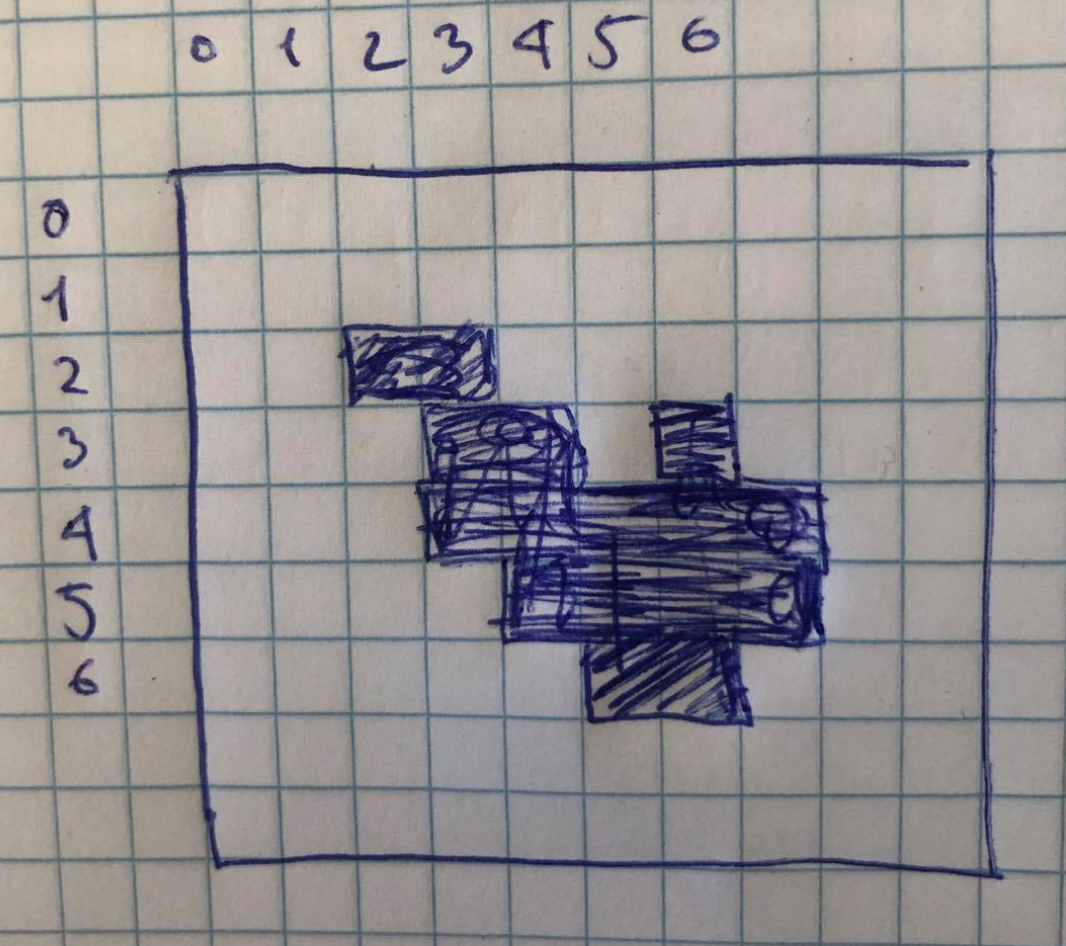

The decoded image (I) is processed with the morphological operation 

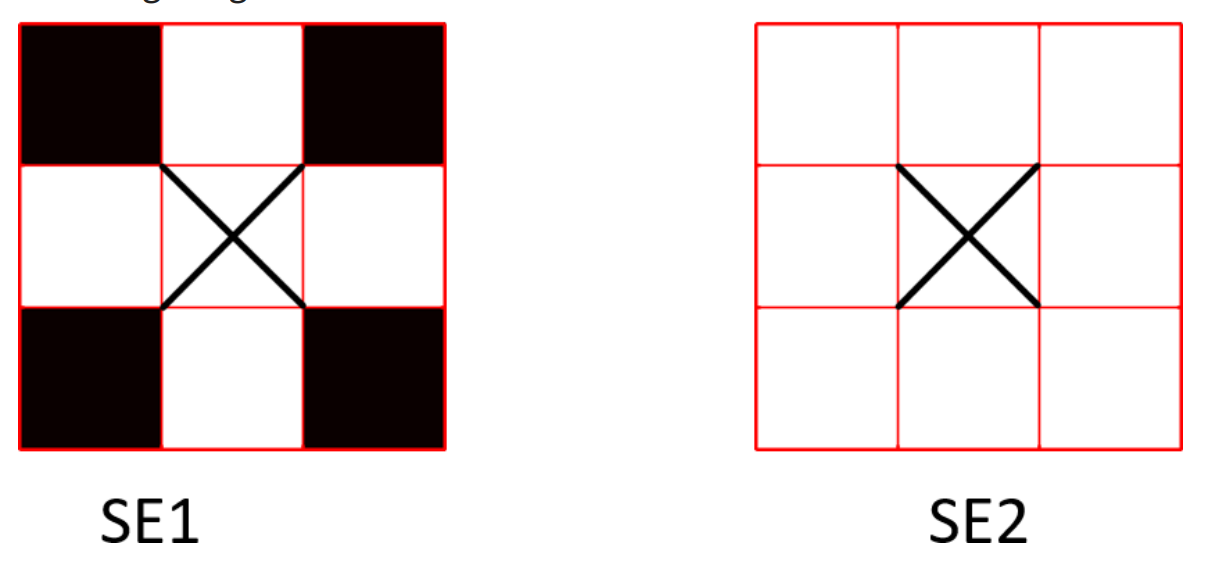

The cross in the structuring elements marks the center. How many foreground pixels are there in the resulting image? 

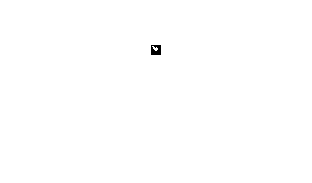

% Man kunne godt 1-indexere det, men det gør ikke noget i dette tilfælde,
% da vi bare skal have summen og der er bare 0'er udenom. Derfor har vi det
% bare som 0-indexeret som det er i opgavebeskrivelsen. 
im = zeros(10);
im(2, 2:3) = 1;
im(3, 3:4) = 1;
im(3, 6) = 1;
im(4, 3:7) = 1;
im(5, 4:7)=1;
im(6, 5:6)=1;

figure;
imshow(im)


SE1 = zeros(3);
SE1(2,1:3) = 1;
SE1(1:3,2) =1;
SE1

SE1 =      0     1     0
     1     1     1
     0     1     0



SE2 = ones(3);
SE2

SE2 =      1     1     1
     1     1     1
     1     1     1



% først erosion
im_eroded = imerode(im,SE1);

% Then closing
im_closed = imclose(im_eroded, SE2);

% sum af antal foreground pixels
sum(im_closed,"all")

ans = 5

## Opg. 7:RGB and HSI picture foreground pixels

The RGB image seen in the figure is converted to the HSI color space. The pixels are thresholded by a threshold of 0.8 on the S values, so pixels with values above are set to foreground. 

How many foreground pixels are there in the resulting image?

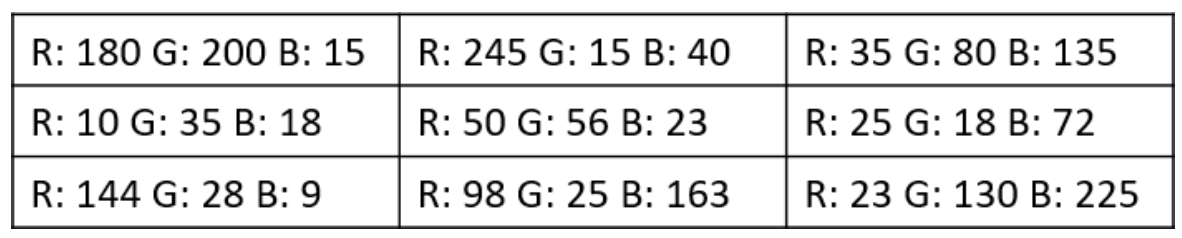

% først converter til HSI ved S formlen 

r = [180, 245, 35; 10, 50, 25; 144, 98, 23];
g = [200, 15, 80; 35, 56, 18; 28, 25, 130];
b = [15, 40, 135; 18, 23, 72; 9, 163, 225];

%exam_funcs.RGB_to_S(r,g,b)

im_rgb = cat(3, r,g,b)

im_rgb = im_rgb(:,:,1) =

   180   245    35
    10    50    25
   144    98    23


im_rgb(:,:,2) =

   200    15    80
    35    56    18
    28    25   130


im_rgb(:,:,3) =

    15    40   135
    18    23    72
     9   163   225



im_hsi = exam_funcs.RGB_to_HSI(im_rgb)

im_hsi = im_hsi(:,:,1) =

    0.1824    0.9842    0.5925
    0.3840    0.1940    0.6857
    0.0208    0.7553    0.5779


im_hsi(:,:,2) =

    0.8861    0.8500    0.5800
    0.5238    0.4651    0.5304
    0.8508    0.7378    0.8175


im_hsi(:,:,3) =

    0.5163    0.3922    0.3268
    0.0824    0.1686    0.1503
    0.2366    0.3739    0.4941


im_s = im_hsi(:,:,2)

im_s =     0.8861    0.8500    0.5800
    0.5238    0.4651    0.5304
    0.8508    0.7378    0.8175



im_thres_s = imbinarize(im_s, .8)

im_thres_s = 3×3 logical array
   1   1   0
   0   0   0
   1   0   1


sum(im_thres_s, "all")

ans = 4

## Opg. 8: normalized cross correlation

A linear gray level transformation is applied to the image seen to the left. The desired minimum pixel value is 12 and the desired maximum pixel value is 196. After the transformation, the pixel values are rounded to the nearest integer. 

A template match is applied to the resulting image, with the template seen to the right. 

What is the normalized cross correlation in the marked pixel? 

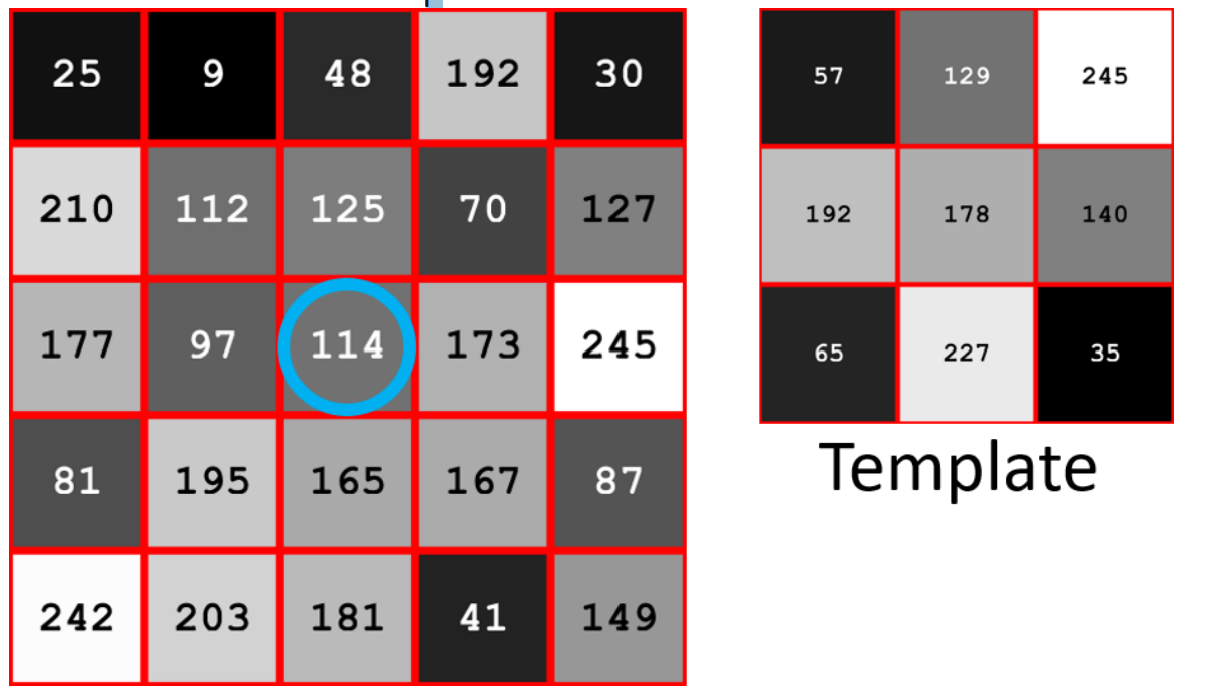

% Histogram stretching formula will be used. 

clc; clear; close all; 

image = [25,9,48,192,30;210,112,125,70,127;177,97,114,173,245;81,195,165,167,87;242,203,181,41,149]

image =     25     9    48   192    30
   210   112   125    70   127
   177    97   114   173   245
    81   195   165   167    87
   242   203   181    41   149


v_min_d = 12

v_min_d = 12

v_max_d = 196

v_max_d = 196

v_min = min(image, [], "all")

v_min = 9

v_max = max(image, [], "all")

v_max = 245

image = ((v_max_d - v_min_d)/(v_max - v_min))*(image - v_min) + v_min_d

image =    24.4746   12.0000   42.4068  154.6780   28.3729
  168.7119   92.3051  102.4407   59.5593  104.0000
  142.9831   80.6102   93.8644  139.8644  196.0000
   68.1356  157.0169  133.6271  135.1864   72.8136
  193.6610  163.2542  146.1017   36.9492  121.1525


image = round(image)

image =     24    12    42   155    28
   169    92   102    60   104
   143    81    94   140   196
    68   157   134   135    73
   194   163   146    37   121



template = [57,129,245;192,178,140;65,227,35]

template =     57   129   245
   192   178   140
    65   227    35


v_min_d_temp = 12

v_max_d_temp = 196

v_min_temp = 35

v_max_temp = 245


corr_2d = sum(image(2:4, 2:4).*template, "all") % indexeringerne er i forhold til at 

corr_2d = 130334

% vi skal have punktet 3,3 i midten af templaten, og vi skal udtage samme
% størrelse som vi har template. 
image_patch_len = sqrt(sum(image(2:4, 2:4).^2, "all"))

image_patch_len = 343.9404

template_patch_len = sqrt(sum(template.^2, "all"))

template_patch_len = 474.3859

NCC = corr_2d/(image_patch_len*template_patch_len)

NCC = 0.7988

## Opg. 9: gammamapping, gradient estimation with prewitt

A gamma mapping with gamme = 1.7 is applied to the image below and the resulting pixel values are rounded to integers. Secondly, the gradient in each pixel is approximated using the horizontal and vertical Prewitt filters. 

What is the magnitude of the gradient in the marked pixel? 

clc; clear; close all; 

image = [208,25,40,36,167;231,71,248,108,9;32,139,244,234,217;233,244,124,202,238;161,246,204,245,173]

image =    208    25    40    36   167
   231    71   248   108     9
    32   139   244   234   217
   233   244   124   202   238
   161   246   204   245   173


im_gamma_mapped = exam_funcs.GammaMap(image,1.7)

im_gamma_mapped =    180     5    11     9   124
   216    29   243    59     1
     7    91   237   220   194
   219   237    75   172   227
   117   240   174   238   132



prewitt_filter = [-1,0,1;-1,0,1;-1,0,1] % vertical

prewitt_filter =     -1     0     1
    -1     0     1
    -1     0     1



first = imfilter(im_gamma_mapped,prewitt_filter)

first =     34  -142    34  -129   -68
   125    88   163  -172  -288
   357   113    94  -133  -451
   568   143    62    67  -630
   477   -87   -67   110  -410


second = imfilter(im_gamma_mapped,prewitt_filter')

second =    245   488   331   303    60
   -87   139   523   507   281
   211    43   153   171   339
   259   196   104  -107   -44
  -456  -531  -484  -474  -399



%What is the magnitude of the gradient in the marked pixel
sqrt(first(3,2)^2 + second(3,2)^2)

ans = 120.9049

## Opg. 10: PCA 

A principal component analysis has been performed on a set of 3x3 images. The average image can be seen below and the 3 first Eigenvectors can be seen as columns in the matrix. A new image is synthesized by adding a linear combination of the 3 first Eigenvectors to the average image. The weights used are 

 what is the resulting pixel value in the upper left corner? 

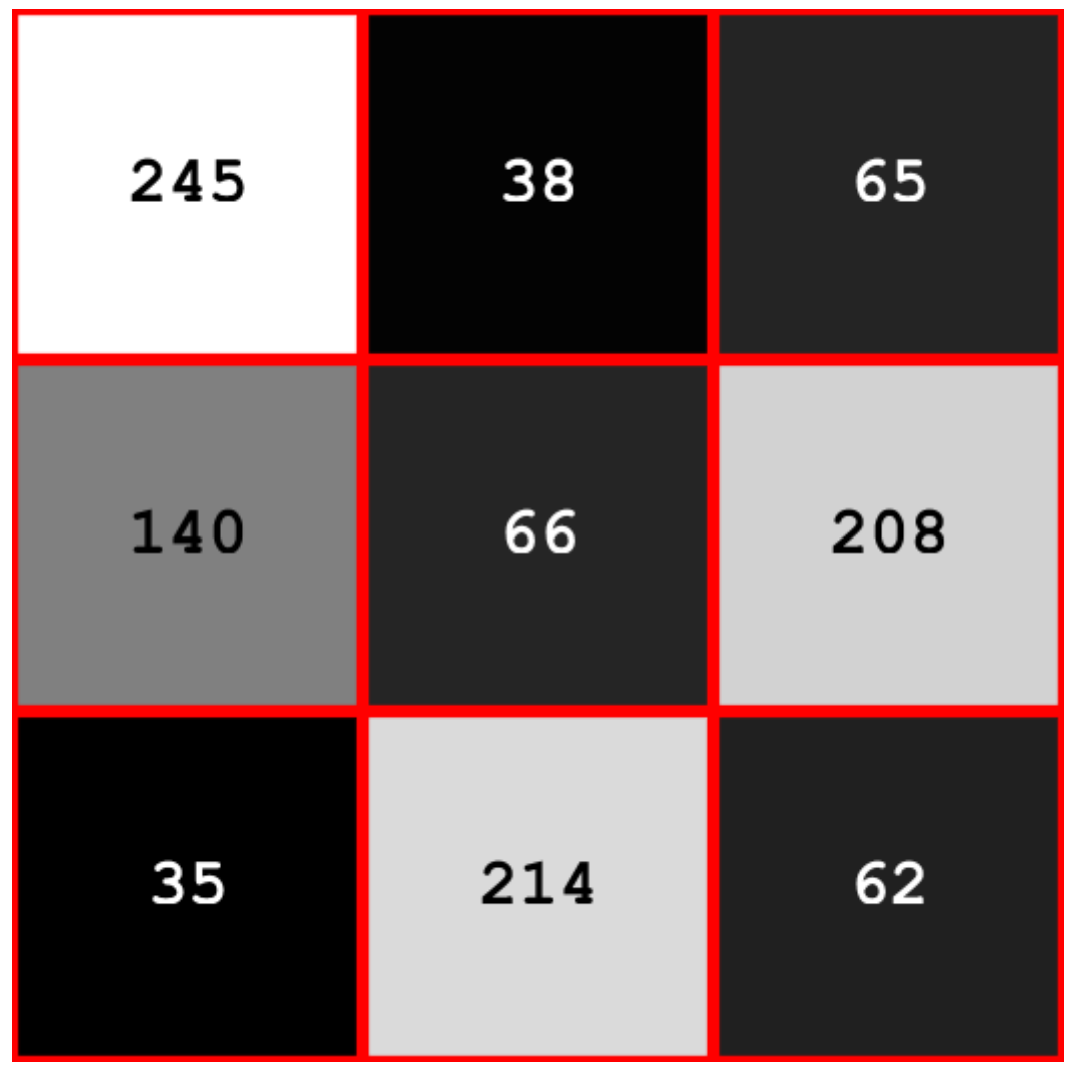

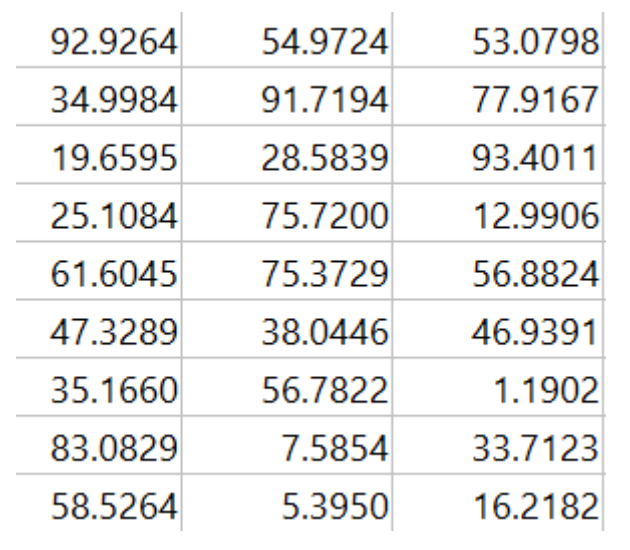

clc; clear; close all; 

image = [245,38,65,140,66,208,35,214,62]

image =    245    38    65   140    66   208    35   214    62


First_row_matrix = [92.9264*0.2,54.9724*-0.7,53.0798*0.5]

First_row_matrix =    18.5853  -38.4807   26.5399



Resulting_pixel_value_of_245 = sum(First_row_matrix)+245

Resulting_pixel_value_of_245 = 251.6445

## Opg. 11:

# Test exam 2021

## Opg 1: Confusion Matrix - True Positive Rate

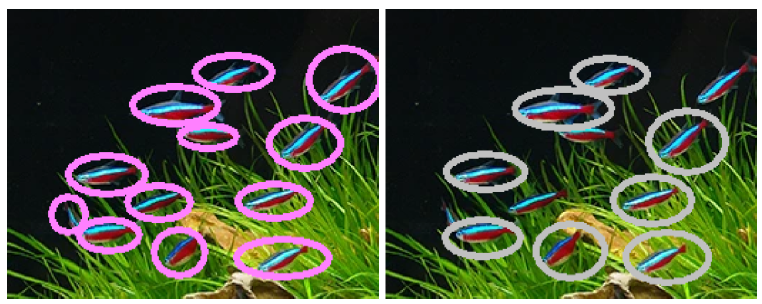

You have made an algorithm that can locate neon fish in an aquarium.

An expert has marked all neon fish in an image as seen in the image to the left. The result of your algorithm is seen in the figure to the right.

What is the true positive rate of your algorithm?

P_expert = 12;
P_algo = 8;
TP = P_algo;
FN = P_expert - P_algo;
TPR = TP/(TP+FN)

TPR = 0.6667

## Opg 2: Filtering/Morphology  - Foreground Pixels After Operations

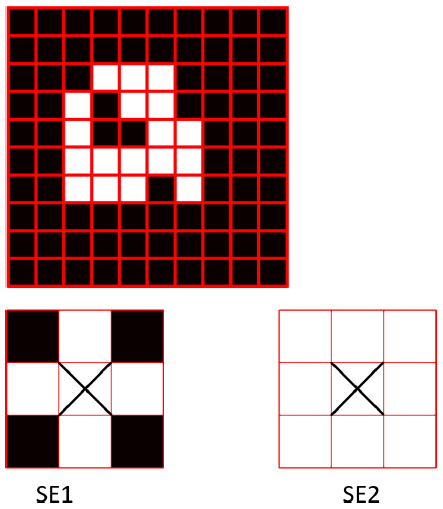

On the image (I) seen in the figure, the operation ($I\cdot SE2)\oplus SE1-1$ is performed. SE1 and SE2 are seen above. White pixels are foreground and black pixels are background. How many foreground pixels are there in the resulting image?

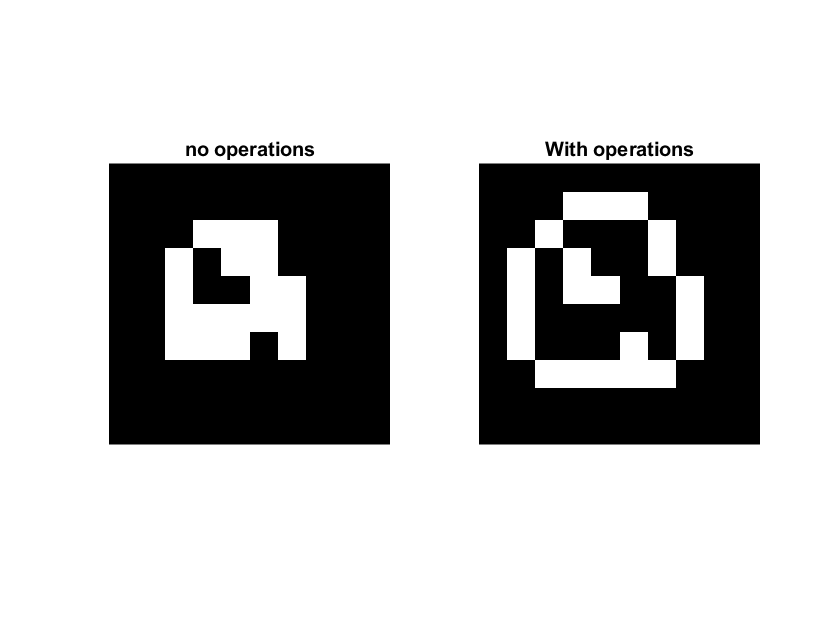

clc; close, clear all;
% define stuff
img = zeros(10,10);
img(3, 4:6) = 1;
img(4, [3, 5:6]) = 1;
img(5,[3, 6:7]) = 1;
img(6, 3:7) = 1;
img(7, [3:5, 7]) = 1;
figure;
subplot(1,2,1)
imshow(img, 'InitialMagnification','fit')
title("no operations")
SE1 = strel("disk", 1);
SE2 = strel("square", 3);

% perform operations
img_operation = imclose(img, SE2);
img_operation = imdilate(img_operation, SE1);
img_operation = img_operation-img;

subplot(1,2,2)
imshow(img_operation, 'InitialMagnification', 'fit');
title("With operations")


foreground_pixels = sum(img_operation, "all")

foreground_pixels = 22

## Opg 3

The point (x, y) = (10, 30) is transformed using a homography with the parameter vector $\vec{d}=[3, 1, 4, 2, 7, 6, 2, 1]^T$. What is the resulting

point (x', y')?

% not part of curriculum

## Opg 4

The point (x, y) = (33, 97) is rotated using a rotation matrix (rotating counter clockwise) with $\theta=8^{o}$. The closest four pixels to the transformed point and their pixel values are:

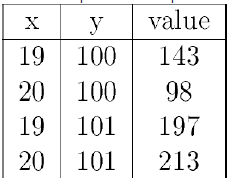

What is the interpolated value using bilinear interpolation (rounded to an integer) in the point?

close; clear all; clc;


## Opg 5

A camera without lens distortions has been used to take a movie of a flying bird. The bird is moving with a constant speed. The bird's path is parallel to the camera's horizontal axis and orthogonal to the optical axis of the camera. The movie has been taken with a distance of 20 meters from the optical center to the path of the bird. The field-of-view of the camera is $28^{o}$. The time from the bird is appearing in the left side of the image to it touches the right side of the image is 2 seconds. 

How fast is the bird flying?

## opg 6

The photo called legocar.png is filtered using an average filter with a filter size of 10. The resulting image is thresholded, so pixels with a value larger than 200 is set to foreground and the rest is set to background. Finally, the BLOBS in the image is found. How many BLOBs are there?

## opg 7

Two sets of corresponding landmarks have been annotated on two photos of hands. The first set is called movingPoints.mat and the second fixedPoints.mat. The moving points are aligned to the fixed points using a similarity transform (rotation, scaling and translation). Finally, the found transform is applied to the first point of the moving points. 

What are the coordinates of the transformed point?